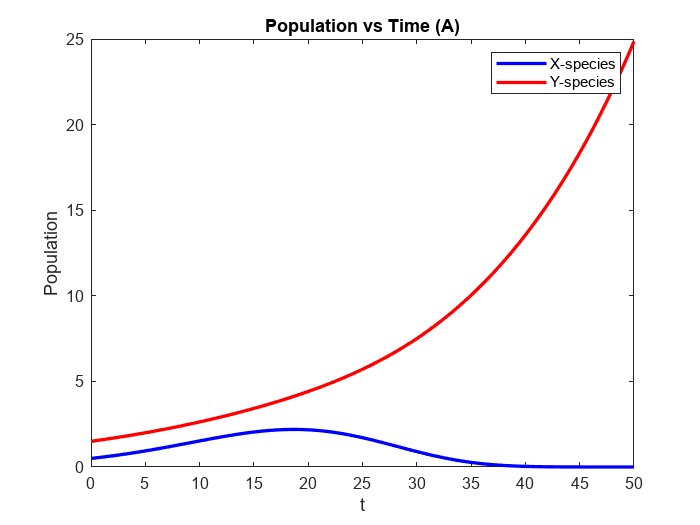

% Parameters
A = 0.21827;
C = 0.06069;
alpha = 0.05289;
beta = 0.00459;
dt = 0.0001;
t_final = 50;

% Function for coupled equations
f = @(t, x, y, B, D) [A*x - B*x^2 - alpha*x*y; C*y - D*y^2 - beta*x*y];

% A. Initial conditions for x(0) = 0.5, y(0) = 1.5, B = D = 0
x0_A = 0.5;
y0_A = 1.5;
B_A = 0;
D_A = 0;

% B. Initial conditions for x(0) = y(0) = 0.5, B = 0.017, D = 0.010
x0_B = 0.5;
y0_B = 0.5;
B_B = 0.017;
D_B = 0.010;

% C. Initial conditions for no competition: alpha = beta = 0
x0_C = 0.5;
y0_C = 0.5;
B_C = 0.017;
D_C = 0.010;

% Function to solve the system using Euler's method
solve_system = @(x0, y0, B, D) euler_method(f, x0, y0, B, D, alpha, beta, dt, t_final);

% Solving system for each scenario
[x_A, y_A] = solve_system(x0_A, y0_A, B_A, D_A);
[x_B, y_B] = solve_system(x0_B, y0_B, B_B, D_B);
[x_C, y_C] = solve_system(x0_C, y0_C, B_C, D_C);

% Plotting
figure;

% A. Plot x and y vs t

plot(0:dt:t_final, x_A, 'b', 'LineWidth', 2);
hold on;
plot(0:dt:t_final, y_A, 'r', 'LineWidth', 2);
xlabel('t');
ylabel('Population');
title('Population vs Time (A)');
legend('X-species', 'Y-species');

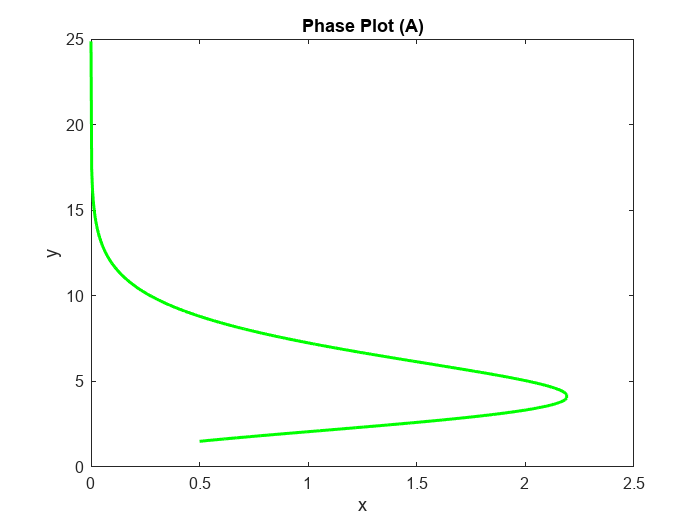


% B. Plot x vs y
figure;

plot(x_A, y_A, 'g', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Phase Plot (A)');


% Maximum values of x and y in scenario A
[max_x_A, max_x_index_A] = max(x_A);
[max_y_A, max_y_index_A] = max(y_A);
disp(['Maximum value of x in scenario A: ', num2str(max_x_A), ' at t = ', num2str(max_x_index_A * dt)]);

Maximum value of x in scenario A: 2.1935 at t = 18.6837


disp(['Maximum value of y in scenario A: ', num2str(max_y_A), ' at t = ', num2str(max_y_index_A * dt)]);

Maximum value of y in scenario A: 24.8607 at t = 50.0001


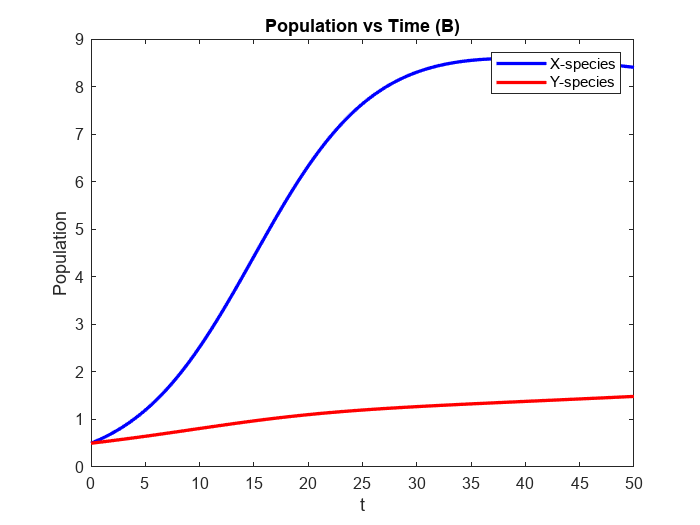


% B. Plot x and y vs t
figure;
%subplot(2, 1, 1);
plot(0:dt:t_final, x_B, 'b', 'LineWidth', 2);
hold on;
plot(0:dt:t_final, y_B, 'r', 'LineWidth', 2);
xlabel('t');
ylabel('Population');
title('Population vs Time (B)');
legend('X-species', 'Y-species');

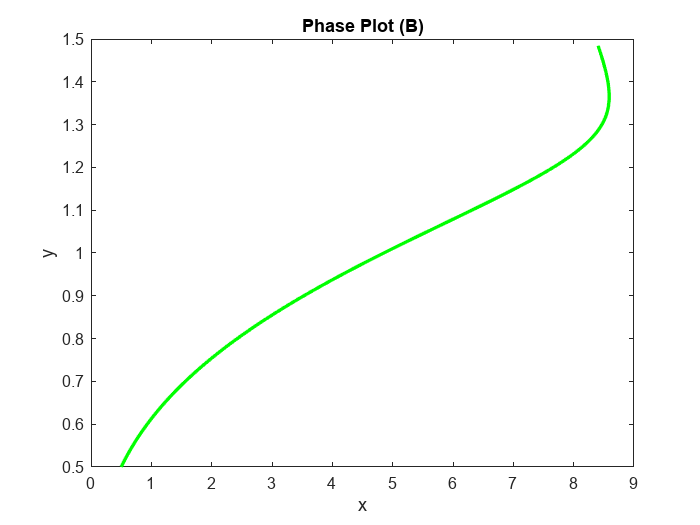


% B. Plot x vs y
figure;
%subplot(2, 1, 2);
plot(x_B, y_B, 'g', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Phase Plot (B)');


% Maximum values of x and y in scenario B
[max_x_B, max_x_index_B] = max(x_B);
[max_y_B, max_y_index_B] = max(y_B);
disp(['Maximum value of x in scenario B: ', num2str(max_x_B), ' at t = ', num2str(max_x_index_B * dt)]);

Maximum value of x in scenario B: 8.5898 at t = 38.6851


disp(['Maximum value of y in scenario B: ', num2str(max_y_B), ' at t = ', num2str(max_y_index_B * dt)]);

Maximum value of y in scenario B: 1.4841 at t = 50.0001


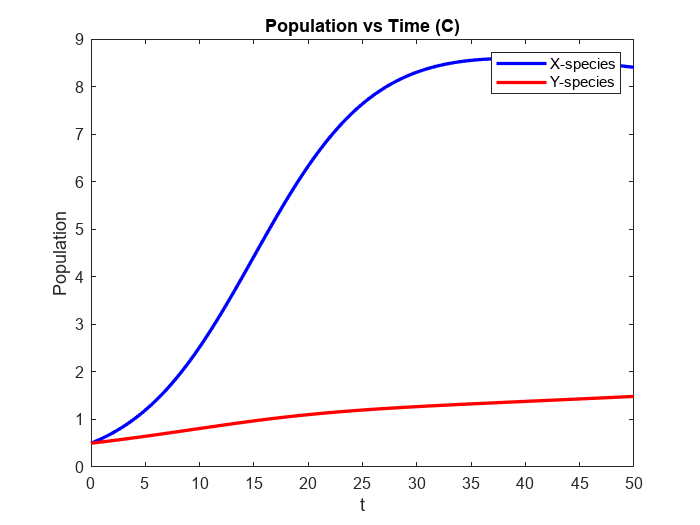


% C. Plot x and y vs t
figure;
%subplot(2, 1, 1);
plot(0:dt:t_final, x_C, 'b', 'LineWidth', 2);
hold on;
plot(0:dt:t_final, y_C, 'r', 'LineWidth', 2);
xlabel('t');
ylabel('Population');
title('Population vs Time (C)');
legend('X-species', 'Y-species');

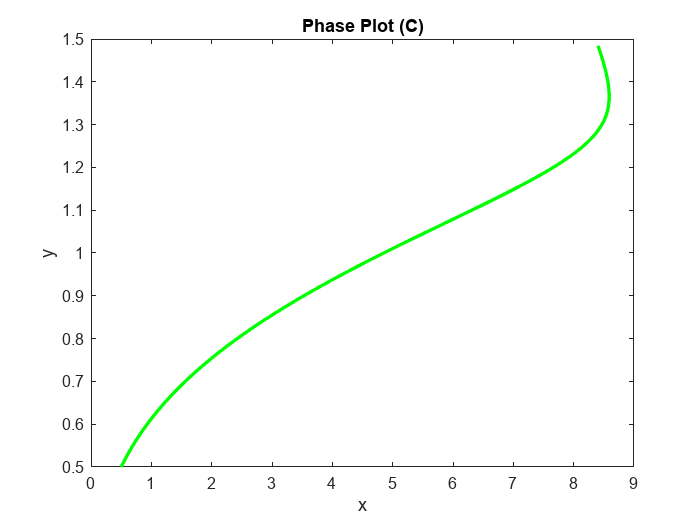


% C. Plot x vs y
figure;
%subplot(2, 1, 2);
plot(x_C, y_C, 'g', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Phase Plot (C)');


% Maximum values of x and y in scenario C
[max_x_C, max_x_index_C] = max(x_C);
[max_y_C, max_y_index_C] = max(y_C);
disp(['Maximum value of x in scenario C: ', num2str(max_x_C), ' at t = ', num2str(max_x_index_C * dt)]);

Maximum value of x in scenario C: 8.5898 at t = 38.6851


disp(['Maximum value of y in scenario C: ', num2str(max_y_C), ' at t = ', num2str(max_y_index_C * dt)]);

Maximum value of y in scenario C: 1.4841 at t = 50.0001



% Function for Euler's method

function [x, y] = euler_method(f, x0, y0, B, D, ~, ~, dt, t_final)
    num_steps = t_final / dt;
    x = zeros(1, num_steps + 1);
    y = zeros(1, num_steps + 1);
    x(1) = x0;
    y(1) = y0;
    for i = 1:num_steps
        dxdt = f(0, x(i), y(i), B, D);
        x(i+1) = x(i) + dxdt(1) * dt;
        y(i+1) = y(i) + dxdt(2) * dt;
    end
end
